# Battery Cell Modeling with Simscape

[⇦ Return to the main menu](matlab:open('../MainMenu.mlx'))

[⇦ Return to the battery modeling menu](matlab:open('../FunctionLibrary/BatteryModeling.mlx')) 

Unveil the secrets of simulating the dynamic world within a battery cell, as we journey through the art of modeling its electrical behavior using Simscape, where code meets energy in a symphony of simulation.

        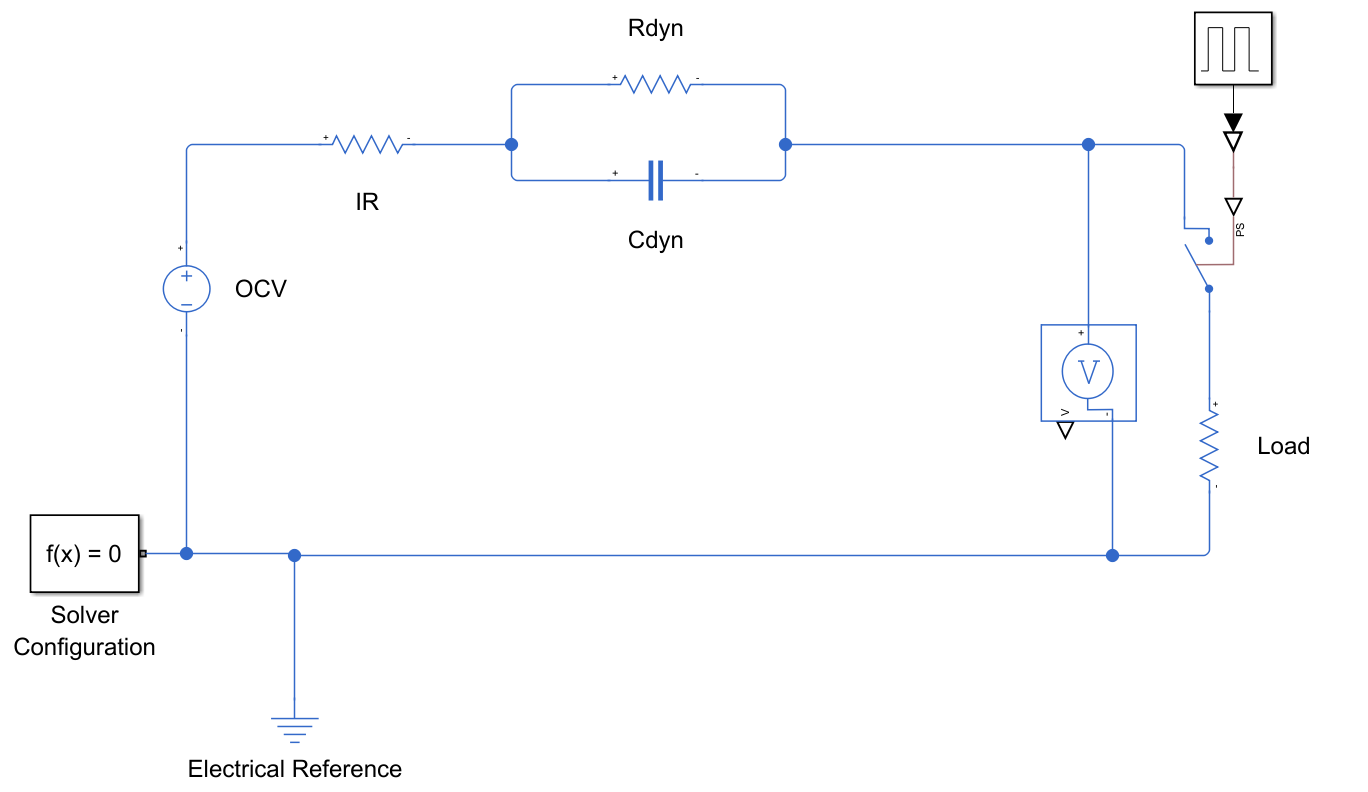

This live script is intended to be used with the code hidden. On the **View** tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code** using the icon   at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2 hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if run out of order.

The    and   icons refer to two different types of interactive activities that you will find in this script. The    usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

## Introduction

Understanding and predicting battery cell behavior under different conditions is key to improving their efficiency, safety, and lifespan. Simulating battery responses to various charging and discharging scenarios helps in designing efficient and reliable battery systems for applications like electric vehicles and renewable energy storage. 

Batteries are complex because they involve many different areas of study like electricity, chemistry, and materials science. Because of this, there are many ways to model or understand batteries, depending on what you're interested in. For example, if someone is working on making a battery better by changing its chemistry or shape, they will focus on the chemical reactions and movement of materials inside the battery. However, if an electrical engineer wants to use the battery in a device, they will mostly care about how the battery behaves electrically. This shows how battery study can vary based on the goals of the person doing the research.

In this script, we will be in the later case, where we will attempt to model the electrical behavior of a battery cell using an Equivalent Circuit Model (ECM). This type of model uses basic electronic components (resistors, capacitors, inductors, etc) to model the battery cell. ECMs are usually rather simple model that allow fast computation and are scalable to model full battery pack containing up to thousands of battery cells.

### Objective

In this script, the focus will be on developing model for a battery cell, using experimental data and information from the manufacturer's data sheet. The construction of the model will include a voltage source, an internal resistance, and RC pairs to represent the electrical behavior of the battery. The calibration process will adjust the model parameters to align with experimental observations, making sure the model accurately reflects the battery's performance under various conditions. The aim is to develop a useful tool for predicting battery performance and optimizing the system.

## Low Fidelity Model

### Battery Characteristic

Before developing an equivalent circuit model for a battery cell, it is necessary to gather some experimental observations. If you have access to a battery cell, a voltmeter, and some resistors (or a flashlight bulb), you can conduct some of these experiments yourself. If not, a Simulink model is provided to observe the same phenomena.

In this experiment we are measuring the **terminal voltage**. The terminal voltage is the voltage across a battery's terminals when it is in use, affected by its internal characteristics, charge state, current flow, and resistance. It differs from the battery's nominal voltage, which is a standard value indicating expected performance.

If you opt for the Simulink model, instructions for conducting the experiment are included within the model. If you choose to perform a physical experiment, use your voltmeter to carry out the following steps:

- Measure the terminal voltage when it is not connected to any load (outside of a circuit).

- Measure the terminal voltage when it is connected to a load (within a circuit).

  **Try.** Choose your preferred method to complete the preliminary work and follow the instructions provided.

ExperimentChoice("None")

 **Exercise 1.** How does turning on the circuit impact the terminal voltage?

Answer = 0;
switch (Answer)
    case 0
        warning("Please select one of the possible answer.")
    case 1
        warning("The voltage should not stay constant, please repeat the experiment.")
    case 2
        disp("Good job! The voltage across the battery decreases when a load is applied.")
    case 3
        warning("The voltage should not increase, please repeat the experiment.")
end

An electric vehicle (EV) manufacturer has requested our assistance in developing an electrical model for its lithium ion battery cell. The detail of the chemical formulation is unknown but we know its capacity is 2800 mAh. They have completed thorough experiments for precise model calibration. To support our development efforts, they have supplied a datasheet containing detailed specifications on the Open Circuit Voltage, Internal Resistance, and State of Charge of the battery cell. This extensive information will allow us to construct an accurate and efficient model that meets their requirements.

- **State of Charge (SoC):** SoC indicates the remaining energy capacity in a battery, shown as a percentage of its full capacity.

- **Open Circuit Voltage (OCV):** OCV represents the terminal voltage when it is disconnected from any load or charging source.

- **Internal Resistance:** describes the resistance inside a battery to the flow of electric current, which influences its efficiency and overall performance.

In the prior experiment, the OCV was recorded using the voltmeter when the battery cell was disconnected from the circuit. The decrease in voltage drop across the battery, observed when connected to a load, was due to the internal resistance.

  **Try.** Explore the datasheet (you can scroll the table to explore the data).

 
load Data/LiIonCell.mat LiIon
Datasheet = LiIon.Characteristic

  **Try.** If you wish to see a visual representation of the data from the constructor datasheet, please click the Plot button below.

 
figure
tiledlayout(2,1)
nexttile
plot(Datasheet.SoC,Datasheet.OCV)
ylabel("OCV (V)")
nexttile
plot(Datasheet.SoC,Datasheet.R0)
ylabel("R0 (Ω)")
xlabel("SoC (-)")

### Model Development

In this section, we will work on developing a mathematical model of the battery cell using simple electronic components. This model is aiming at representing the voltage drop that was captured in the experiment accomplished in the beginning of this script. The first step in developing any mathematical model is to identify all the known parameters.

 **Exercise 2.** Based on the battery datasheet and the specifications shared by the manufacturer. What parameters do you know about the battery or can be measured easily?

ParameterCheck(OCV = false,...
    InternalResistance= false,...
    SOC = false,...
    SOH = false,...
    Capacity = false,...
    ElectroChemicalProp = false,...
    CyclingLife = false)
 

It would be really ambitious to try develop a highly accurate model from the start. So we will try to simplify the problem as much as possible, develop a model for that problem and verify how accurate this first model is. In a second time, we will be able to iterate on the model and increase its accuracy if need be.

 **Exercise 3.** Identify all of the assumptions that can be made to simplify the problem.

AssumptionCheck(ConstantVoltage = false,...
    ConstantResistance = false,...
    InstantaneousResponse = false,...
    ThermalEffect = false,...
    ElectrochemicalDynamic = false)
 

Now that we have identified the parameters of the problem and the assumption that we will be making. We can define a constant value for the internal resistance and the OCV. We could define the this function as the mean, max, min, or median value of the measured OCV and internal resistance.

  **Try.** Select a function to define the OCV (`OCV`) and internal resistance (`IR`).

SelectFun = @mean;
OCV = SelectFun(Datasheet.OCV);
R0 = SelectFun(Datasheet.R0);
disp("OCV = "+OCV+" (V)"+newline+...
    "Internal Resistance = "+R0+" (Ω)");
 

 **Reflect.** What effect could this selection have on the model's results? 

We can define a 10 seconds scenario for battery usage by defining a profile of current drawn from the battery. For this purpose, we will be using the rectangular pulse function to define the discharge of a battery as follow:


$$\begin{cases}
i(t) = 0 A \qquad 0 \le t < 2\ \\
i(t) = 1 A \qquad 2 \le t < 5\ \\
i(t) = 0 A \qquad 5 \le t < 10\\
\end{cases}$$


  **Try.** Define all the problem parameters

syms t
i = sym('i')
i(t) = rectangularPulse(2,5,t);
figure
fplot(t,i,[0 10])
xlabel("t (s)")
ylabel("i(t) (A)")
title("Discharge scenario")
grid on
set(gca,"YLimitMethod","padded")
 

In this section of the script, you will construct your model in Simscape Electrical. If you are not familiar with Simscape, completing [Simscape Onramp](https://matlabacademy.mathworks.com/details/simscape-onramp/simscape) is recommended.

  **Try.** Create a new Simscape model.

Mdl = ssc_new('BatteryModel','electrical');
Blocks = Simulink.findBlocks(Mdl);
BlockName = getfullname(Blocks);
idx = contains(BlockName,'PS-Simulink') | ...
    contains(BlockName,'Simulink-PS') | ...
    contains(BlockName,'Spectrum') | ...
    contains(BlockName,'Scope') | ...
    contains(BlockName,'Spectrum');
delete_block(Blocks(idx))
delete_line(find_system(Mdl, 'FindAll', 'on', 'Type', 'line', 'Connected', 'off'))
delete(find_system(Mdl,'FindAll','on','Type','annotation'));
 

 **Exercise 4.** Please follow the instructions below to verify your model.

- Insert a **Voltage Source block** (located in Simscape > Foundation Library > Electrical > Electrical Sources within the Library Browser).

- Rename the block to **OCV**.

- Set its DC Voltage to `OCV` (a variable already created in your workspace).

- Connect the Solver to one terminal of the newly added block.

block = find_system(Mdl,'Name','OCV');
if isempty(block)
    warning("Can not find a block name OCV")
else
    a = get_param(block,'dc_voltage');
    if a == 'OCV'
       disp("Good job! You parametrized the voltage source correctly.")
    else
        warning("DC voltage should be set as 'AvgOCV'")
    end 
end
 

 **Exercise 5.** Complete the following steps before checking your model.

- Place a **Resistor block** (available in Simscape > Foundation Library > Electrical > Electrical Elements within the Library Browser).

- Rename the block to **R0**.

- Link its positive terminal to the positive terminal of the Voltage Source.

- Assign its Resistance value to `R0` (a variable that exists in your workspace and was calculated earlier).

block = find_system(Mdl,'Name','R0');
if isempty(block)
    warning("Can not find a block name R0")
else
    a = get_param(block,'R');
    if a == 'R0'
       disp("Good job! You parametrized the internal resistance correctly.")
    else
        warning("DC voltage should be set as 'R0'")
    end 
end
 

 **Exercise 6.** Please follow the steps below before evaluating your model.

- Insert a **Pulse Current Source** (located in Simscape > Electrical > Sources within the Library Browser).

- Rename this block to Load.

- Connect its positive terminal to the negative terminal of the previously added Resistor.

- To model the usage profile defined above assign:

block = find_system(Mdl,'Name','Load');
if isempty(block)
    warning("Can not find a block named Load")
else
    I1 = get_param(block,'I1');
    I2 = get_param(block,'I2');
    TD = get_param(block,'TD');
    PW = get_param(block,'PW');
    PER = get_param(block,'PER');
    err = false;
    if I1 ~= '0'
        err = true;
        warning("I1 voltage should be set to 0 (A).'")
    end 
    if I2 ~= '1'
        err = true;
        warning("I2 voltage should be set to 1 (A).'")
    end 
    if TD ~= '2'
        err = true;
        warning("DC voltage should be set to 1.'")
    end 
    if PW ~= '3'
        err = true;
        warning("DC voltage should be set to 1.'")
    end 
    if PER ~= '10'
        err = true;
        warning("DC voltage should be set to 1.'")
    end 
    if ~err
        disp("Good job! You set all the paremeters correctly.")
    end

end
 

 **Exercise 7.** Complete the following instructions before reviewing your model.

- Connect the electrical reference and solver to the electrical circuit.

- Insert a Voltage Sensor block (found in Simscape > Foundation Library > Electrical > Electrical Sensors within the Library Browser) and arrange it to measure the terminal voltage (voltage across the load).

- Name the Voltage Sensor block "Terminal Voltage".

By now, your model should resemble the following layout:

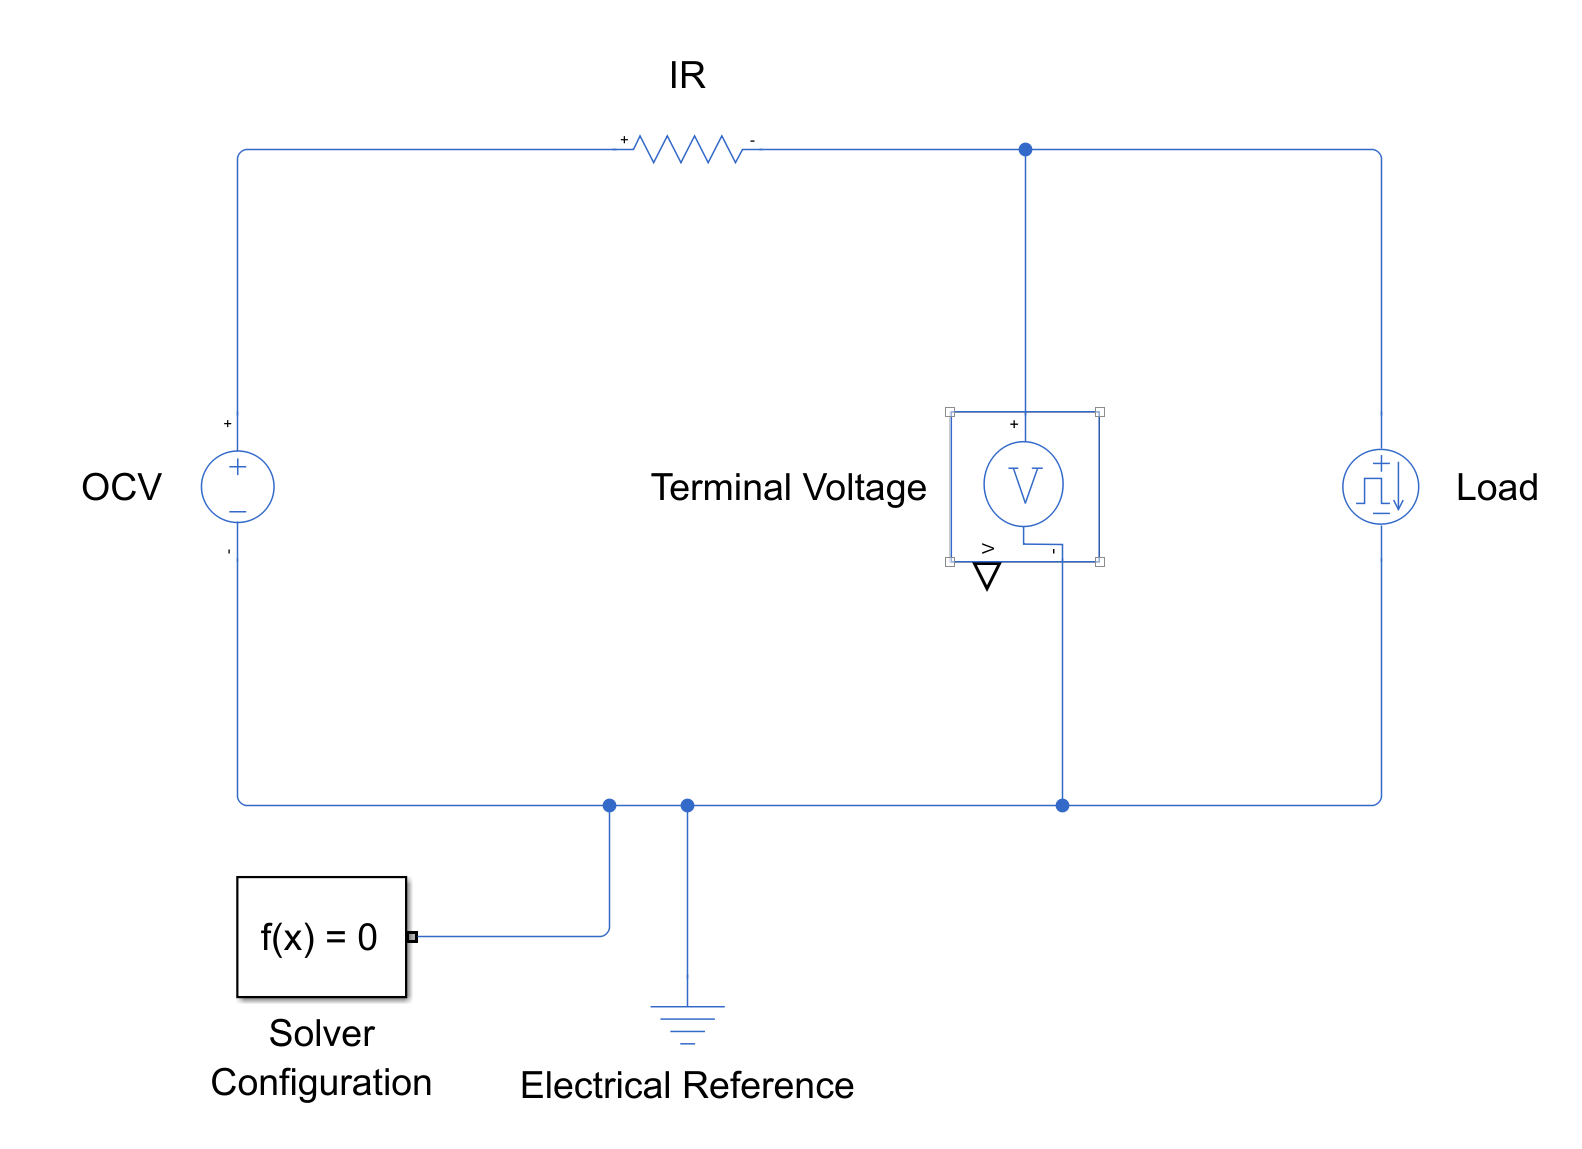

block = find_system(Mdl,'Name','Terminal Voltage');
if isempty(block)
    warning("Can not find the Voltage Sensor")
else
   disp("Good job! Your model is ready.")
end
 

  **Try.** Attempt the following steps to observe the model's behavior:

- Run the model for a duration of 10 seconds.

- Open the Simscape Results Explorer, which can be found in the REVIEW RESULTS section of the SIMULATION tab on the Toolstrip.

- Examine the voltage across the load as measured by the voltage sensor and compare it to the voltage supplied by the voltage source (OCV).

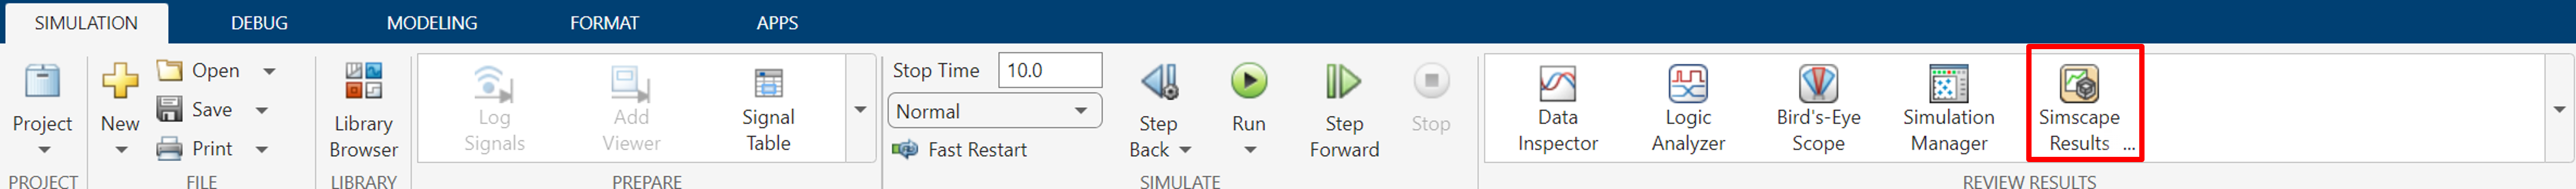

### Further Exploration

  **Try.** Change the function used to estimate the OCV and internal resistance. How does the terminal voltage changes?

## Higher Fidelity Model

In the previous section, we developed an Equivalent Circuit Model (ECM) capable of to capture for the internal resistance of the battery. This model is adequate for discharge with constant or slowly fluctuating current discharge. The figure below represent the terminal voltage of a lithium ion battery cell during a 3 seconds pulsed discharge:

In the current state, our model is able to represent everything that is represented with a black line. The colored lines (green and orange) presents dynamic behavior that our model is not able to reproduce.

- **Polarization (green):** the internal transport processes and chemical reaction within the battery cell have their dynamic when current is applied or drawn.

- **Linear voltage drop (orange)**: as seen in the battery datasheet, the battery's open circuit voltage decreases with the SoC. The linear decrease in terminal voltage is characteristic of the battery charge loss during the discharge.

 **Reflect.** Do I need to account for all of this behavior? What kind of model should I build?

In this part of the script, we will try to capture the polarization (green curve) with our model. Because the time scale of this phenomena (~ hundreds of milliseconds) is relatively short, it would not be be important if our battery were used to power our system at a relative constant current for times larger than the polarization time scale (for example to power outdoor lights at nights). Our battery are being used for an electric vehicle where the power being drawn by the motor is constantly changing at time scale (~ seconds) that are close enough to the polarization time scale to have an effect on the terminal voltage. Therefore, in our case, adding polarization is necessary.

### Adding dynamic behavior

In order to capture the polarization curve, we are going to add electronic components to our ECM to add a dynamic behavior modeling the polarization.

 **Exercise 8.** What is the first electronic component that you learned of, which could be used to introduce a dynamic behavior?

switch 1
    case 0
        warning("Please, select one of the other options in the drop down list.")
    case 2
        disp("Good job! The capacitor will add a time component to the model, and keep the model really simple.")
        [img,~,a] = imread(fullfile("Images","CircuitPolarization.png"));
        f = imshow(img,InitialMagnification=50);
        f.AlphaData = a;
    otherwise
        warning("There is probably a simpler component that could be used here.")
end

Following discussions with the battery manufacturer, they indicated that the dynamic time constant is approximately 0.2 s. Through experimentation, it was estimated that the voltage decreases by about 0.02 V during this exponential phase when the discharge rate is set at 1 A. To model this behavior, an RC circuit will be added to the previous model.

 **Exercise 9.** Using Ohm's law, the polarization voltage and the discharge rate current, compute the polarization resistance.

Rpol =  0;
if ismembertol(Rpol,0.02/1,1e-5)
    disp("Good job! You computed the resistance in the RC circuit correctly.")
else
    warning("The resistance should be voltage (0.02 V) divided by current (1 A).")
end

The time-constant of an RC system can be define as:


$$\tau_{pol} = R_{pol}C_{pol}$$


with $\tau$ being the time constant, R and C being the resistance and capacitance of the circuit.The time-constant of an RC system can be define as:


$$\tau_{pol} = R_{pol}C_{pol}$$


with $\tau$ being the time constant, R and C being the resistance and capacitance of the circuit.

 **Exercise 10.** Based on the polarization time constant, and the polarization resistance, compute the capacitance.

Cpol =  0;
if ismembertol(Cpol,10,1e-5)
    disp("Good job! You computed the capacitor value in the RC circuit correctly.")
else
    warning("The resistance should be time constant (200 ms) divided by resistance (0.02 Ohm).")
end

  **Try.** Click the button below to open the model with the RC circuit.

open(fullfile("Models","DynamicSimscapeModel.slx"))
 

 **Exercise 11.** Modify the capacitor value and resistor value with the value calculated previously.

Mdl = load_system(fullfile("Models","DynamicSimscapeModel.slx"));
Block = find_system(Mdl,'Name','Rpol');
err = false;
if ~ismembertol(str2num(get_param(Block,'R')),Rpol,1e-3)
    err = true;
    warning("The resistance in the Rdyn block should be set to 0.2 Ohm.")
end
Block = find_system(Mdl,'Name','Cpol');
if ~ismembertol(str2num(get_param(Block,'C')),Cpol,1e-3)
    err = true;
    warning("The capacitance in the Cdyn block should be set to 1 F.")
end
if ~err
    disp("Good job! You defined the RC circuit correctly.")
end
 

  **Try.** Run the model and observe the voltage measure across the load.

## Conclusion

With this model, the EV company is going to be able to simulate the behavior of the hundreds of battery cell used in their EV over driving scenario usage. This could be used to validate the design choice in term of battery configuration and helps tuning the control algorithm. 

### Further Exploration

If you are interested in exploring how different tools can be applied to the same problem, you might consider revisiting the battery modeling activity with an alternative tool. Whether you initially used MATLAB, Simulink, or Simscape, trying to model the battery cell with one of the other tools can provide new insights and deepen your understanding of both the modeling process and the tool itself.

[⇦ Return to the battery modeling menu](matlab:open('../FunctionLibrary/BatteryModeling.mlx'))

Additionally, we offer another script focused on using MATLAB to model the heat generated by a battery cell during discharge. This script presents an opportunity to further explore MATLAB capabilities in simulating and analyzing thermal behaviors within battery cells, complementing your knowledge of battery modeling from a different perspective.

[⇦ Try thermal modeling](matlab:open('../Scripts/ThermalModeling.mlx'))

## Helper Functions

function ParameterCheck(opts)
arguments
    opts.OCV (1,1) logical
    opts.InternalResistance(1,1) logical
    opts.SOC (1,1) logical
    opts.SOH (1,1) logical
    opts.Capacity (1,1) logical
    opts.ElectroChemicalProp (1,1) logical
    opts.CyclingLife (1,1) logical
end

    err = false;
    if ~opts.OCV
        err = true;
        warning("The OCV is in the battery characterstics.")
    end
    if ~opts.InternalResistance
        err = true;
        warning("The IR is in the battery characterstics.")
    end
    if ~opts.SOC
        err = true;
        warning("The SoC is known.")
    end
    if opts.SOH
        err = true;
        warning("The SoC is unknown.")
    end
    if ~opts.Capacity
        err = true;
        warning("The capacity is in the battery characterstics.")
    end
    if opts.ElectroChemicalProp
        err = true;
        warning("The electro-chemical properties are unknown.")
    end
    if opts.CyclingLife
        err = true;
        warning("The number of lfe cycle is unknown.")
    end

    if ~err
        disp("Good job! You identified all of the known parameters.")
    else
        warning("")
    end

end


function AssumptionCheck(opts)
arguments
    opts.ConstantVoltage (1,1) logical
    opts.ConstantResistance (1,1) logical
    opts.InstantaneousResponse (1,1) logical
    opts.ThermalEffect (1,1) logical
    opts.ElectrochemicalDynamic (1,1) logical
end

    if ~opts.ConstantVoltage
        warning('We are considering a constant voltage. Please check and make necessary changes.')
    end
    if ~opts.ConstantResistance
        warning('We are considering a constant internal resistance. Please check and make necessary changes.')
    end
    if ~opts.InstantaneousResponse
        warning('We are considering instantaneous response. Please check and make necessary changes.')
    end
    if ~opts.ThermalEffect
        warning('We are not modeling the thermal effect. Please check and make necessary changes.')
    end
    if ~opts.ElectrochemicalDynamic
        warning('We are not modeling the electrochemical dynamic. Please check and make necessary changes.')
    end

    if opts.ConstantVoltage && opts.ConstantResistance && opts.InstantaneousResponse && opts.ThermalEffect && opts.ElectrochemicalDynamic
        disp('Good job! You have identified that all of those assumptions are being made.')
    end

end

function ExperimentChoice(Choice)
    switch Choice
        case "None"
            warning("Please select either Simulink Model or Experiment")
        case "Simulink"
            open(fullfile("Models","ECMExperiment.slx"))
        case "Experiment"
            [img,~,a] = imread("WiringDiagram.png");
            f = imshow(img,InitialMagnification=50);
            f.AlphaData = a;
    end
end

[⇦ Return to the main menu](matlab:open('../MainMenu.mlx'))

[⇦ Return to the battery modeling menu](matlab:open('../FunctionLibrary/BatteryModeling.mlx'))